# **TU: Frequecy Features Extraction**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

Prerequisite:  Review how to apply one-single sided power using FFT 

Frequency Features of 

- Frequency Center

- RMS frequency

- Root variance frequency

> Need to use  getFFT.m   

## Include path

addpath('Library')  

## Dataset

### Generate Signals

A signal with a sampling frequency of 1 kHz and a signal duration of 1 second.

Form a signal containing a 50 Hz sinusoid and 120Hz sinusoid 

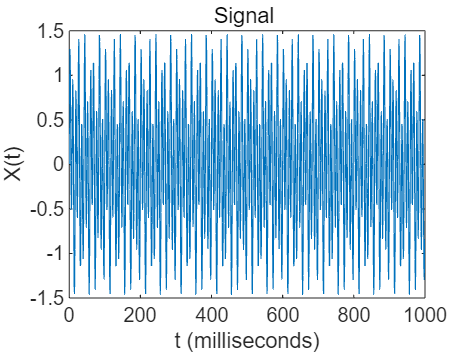

close all
clear 

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = 1000;             % Length of signal
t = (0:N-1)*T;        % Time vector


% Information Signal 
fa=50;      % 10Hz signal
fa2=120;    % 55Hz signal
X = 0.0 + 0.5* sin(2.0*pi*fa*t)+1*sin(2.0*pi*fa2*t); 

% Plot signals
figure()
plot(1000*t,X)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('X(t)')

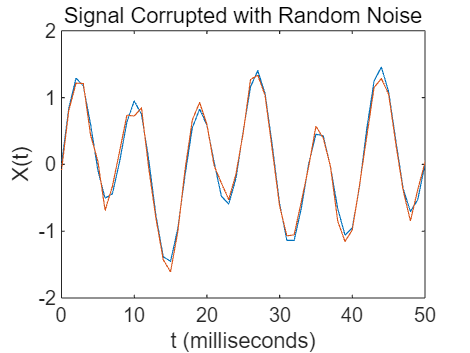

% Noise
noise=0.1*randn(size(t));

% Mixed Signal
Xm = X+noise; 


% Plot signals
figure(1)
plot(1000*t,X, 1000*t,Xm)
title('Signal Corrupted with Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
xlim([0 50])

## Exercise 1: Frequency Features (simple)

- Frequency Center

- RMS frequency

- Root variance frequency

### 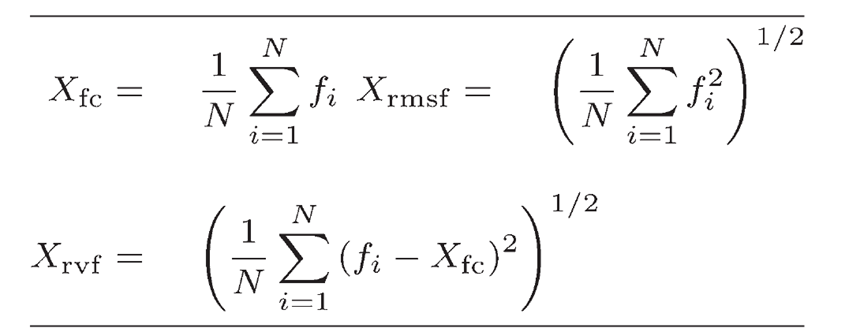

### FFT analysis

%%% Input for FFT
x=X;    %x=Xm;
L=length(x);

%%% Apply FFT of x
% single-sided spectrum P1
% YOUR CODE GOES HERE
Y = fft(x, L);
P2 = abs(Y/L);
P = P2(1:L/2+1);
P(2:end-1) = 2*P(2:end-1);
f = 0:Fs/L:Fs/2;  


Plot single-sided spectrum P

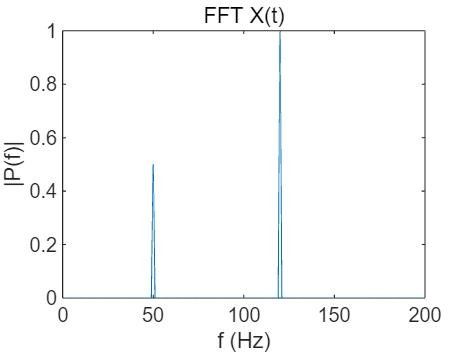

figure
plot(f,P) 
title('FFT X(t)')
xlabel('f (Hz)')
ylabel('|P(f)|')
xlim([0 200])

### Frequency features

% x:        Input data
% xfeature: Table for feature of x


F=P;        %=Xm
N=length(F);

% Create table variable xfeature
xfeature = table;

**Frequency Center**

% YOUR CODE GOES HERE
xfeature.fc=sum(f.*F)/sum(F);

**RMS frequency**

% YOUR CODE GOES HERE
xfeature.rmsf=sqrt(sum((f.^2).*F)/sum(F));

**Root variance frequency**

% YOUR CODE GOES HERE
xfeature.rvf=sqrt(xfeature.rmsf^2-xfeature.fc^2);

## Exercise 2

Compare the  features of signals with and without noise added.

% ----- 1) Without noise -----
x = X;
L = length(x);
Y = fft(x,L);
P2 = abs(Y/L);
P = P2(1:L/2+1);
P(2:end-1) = 2*P(2:end-1);
f = 0:Fs/L:Fs/2;

F = P;
xfeature_clean.fc   = sum(f.*F)/sum(F);
xfeature_clean.rmsf = sqrt(sum((f.^2).*F)/sum(F));
xfeature_clean.rvf  = sqrt(xfeature_clean.rmsf^2 - xfeature_clean.fc^2);

% ----- 2) With noise -----
x = Xm;
Y = fft(x,L);
P2 = abs(Y/L);
P = P2(1:L/2+1);
P(2:end-1) = 2*P(2:end-1);

F = P;
xfeature_noisy.fc   = sum(f.*F)/sum(F);
xfeature_noisy.rmsf = sqrt(sum((f.^2).*F)/sum(F));
xfeature_noisy.rvf  = sqrt(xfeature_noisy.rmsf^2 - xfeature_noisy.fc^2);

% ----- 비교 출력 -----
disp('Without noise:')

Without noise:


disp(xfeature_clean)

      fc: 96.6667
    rmsf: 102.1437
     rvf: 32.9983



disp('With noise:')

With noise:


disp(xfeature_noisy)

      fc: 198.4434
    rmsf: 243.6130
     rvf: 141.3065



## Exercise 3

Create a module, named as `freqFeatures.m` that returns time-domain features in table form.

Save it in `\IAIA\Library\` folder

See [**freqFeatures_student.m**](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Library) as an example.

Example: 

%P=getFFT(x,L);
% YOUR CODE GOES HERE
F = P;                  % FFT 전력 스펙트럼
f = Fs*(0:(L/2))/L;
xfeature = freqFeatures_student(F,f);
disp(xfeature)

      fc       rmsf      rvf  
    ______    ______    ______

    198.44    243.61    141.31

